% Program P3_1
% Evaluation of the DTFT
clf;

% Compute the frequency samples of the DTFT
w = -2*pi:8*pi/511:2*pi;

% Define the values of M to loop through
M_values = [10];

for ii = 1:length(M_values)
    % Get the current value of M
    M = M_values(ii);
%     disp(["M="num2str(M)]);
disp(['M=' num2str(M)]);
    
    % Compute the filter coefficients and frequency response
%     num = (1/M)*ones(1,M);
%     den = 1;
    num = [.15,0,-.15];
    den=[1,-.5,.7];
%     den = [.7,-.5,1];
% num = [0,1,-1.2,1];
% den = [1,-1.3,1.04,-.222];
    h = freqz(num, den, w);

    % Plot the DTFT and add the text
    figure;

    subplot(2,2,1)
    plot(w/pi,real(h));grid
    title('Real part of H(e^{j\omega})')
    xlabel('\omega /\pi');
    ylabel('Amplitude');
    
    subplot(2,2,2)
    plot(w/pi,imag(h));grid
    title('Imaginary part of H(e^{j\omega})')
    xlabel('\omega /\pi');
    ylabel('Amplitude');
    
    subplot(2,2,3)
    plot(w/pi,abs(h));grid
    title('Magnitude Spectrum |H(e^{j\omega})|')
    xlabel('\omega /\pi');
    ylabel('Amplitude');
    
    subplot(2,2,4)
    plot(w/pi,angle(h));grid
    title('Phase Spectrum arg[H(e^{j\omega})]')
    xlabel('\omega /\pi');
    ylabel('Phase, radians');
end

% Program P3_1
% Evaluation of the DTFT
clf;

% Compute the frequency samples of the DTFT
w = 0:4*pi/511:1*pi;

% Set the value of M
M = 7;

% Compute the filter coefficients and frequency response
num = [0, 1, -1.2, 1];
den = [1, -1.3, 1.04, -0.222];
h = freqz(num, den, w);

% Plot the DTFT and add the text
figure;

subplot(2,2,1)
plot(w/pi,real(h));grid
title('Real part of H(e^{j\omega})')
xlabel('\omega /\pi');
ylabel('Amplitude');

subplot(2,2,2)
plot(w/pi,imag(h));grid
title('Imaginary part of H(e^{j\omega})')
xlabel('\omega /\pi');
ylabel('Amplitude');

subplot(2,2,3)
plot(w/pi,abs(h));grid
title('Magnitude Spectrum |H(e^{j\omega})|')
xlabel('\omega /\pi');
ylabel('Amplitude');

subplot(2,2,4)
plot(w/pi,angle(h));grid
title('Phase Spectrum arg[H(e^{j\omega})]')
xlabel('\omega /\pi');
ylabel('Phase, radians');

% Compute and plot the group delay
[gd, w_gd] = grpdelay(num, den, w);
figure;
plot(w_gd/pi, gd);grid
title('Group Delay of H(e^{j\omega})')
xlabel('\omega /\pi');
ylabel('Group Delay, samples');

clf;
% Input the coefficients of the numerator and denominator of G(z)
num = [.15,0,-.15];
den=[1,-.5,.7];
% den = [.7,-.5,1];


% Prompt user to input the value of L
L = 100

% Compute the inverse z-transform using the built-in function iztrans
syms z n;
G = poly2sym(num, z)/poly2sym(den, z);
g = iztrans(G);
g_n = subs(g, n, 0:L-1);

% Plot the sequence using the stem command
% subplot(2,1,1)
% stem(0:L-1, double(g_n));
% title('Inverse z-transform of G(z)');
% xlabel('n');
% ylabel('g[n]');

% Plot the pole-zero plot using the zplane command
subplot(2,1,1)
zplane(num, den);
title('Pole-Zero Plot of G(z)');

% Program P4_1
% Impulse Response of Truncated Ideal Lowpass Filter
clf;
fc = 0.25;
n = [-6.5:1:6.5];
y = 2*fc*sinc(2*fc*n);k = n+6.5;
stem(k,y);title('N = 13');axis([0 13 -0.2 0.6]);
xlabel('Time index n');ylabel('Amplitude'); grid

% Program to compute and plot the impulse response of an FIR lowpass filter
clf;

% Define the filter parameters
L = 20;         % filter length
wc = 0.45*pi;   % cutoff frequency in radians

% Compute the impulse response using the formula for an FIR filter
n = 0:L-1;
h = wc/pi * sinc(wc/pi * (n - (L-1)/2));

% Plot the impulse response using the stem command
stem(n, h);
title('Impulse Response of FIR Lowpass Filter');
xlabel('Time index n');
ylabel('Amplitude');

% Impulse Response of Truncated Ideal Lowpass Filter
clf;

% Define filter parameters
fc = 0.65; % cutoff frequency
N = 14; % filter length (must be even)

% Compute impulse response
n = -(N/2):(N/2);
h = 2*fc*sinc(2*fc*n);

% Plot impulse response
stem(n, h);
title(sprintf('N = %d, fc = %g', N, fc));
xlabel('Time index n');
ylabel('Amplitude');
grid on;
axis tight;

% Compute and plot the amplitude response of Truncated Ideal Lowpass Filter
clear;
N_values = [1, 3, 10, 17, 20];

% Loop through different values of N
for i = 1:length(N_values)
    N = N_values(i);

    % Compute impulse response and magnitude spectrum
    No2 = N/2;
    fc = 0.25;
    n = [-No2:1:No2];
    y = 2*fc*sinc(2*fc*n);
    w = 0:pi/511:pi;
    h = freqz(y, [1], w);

    % Plot magnitude spectrum
    subplot(length(N_values), 1, i);
    plot(w/pi, abs(h));
    grid on;
    title(['|H(e^{j\omega})|, N=' num2str(N)]);
    xlabel('\omega /\pi');
    ylabel('Amplitude');
end

% Gain Response of a Moving-Average Lowpass Filter
clf;
M = 2;
num = ones(1,M)/M;

w = linspace(0, pi, 1000);
H = freqz(num, 1, w);
g = 20*log10(abs(H));

plot(w/pi, g);
grid on;
axis([0 1 -50 0.5]);
xlabel('\omega /\pi');
ylabel('Gain in dB');
title(['M = ', num2str(M)]);

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);

% Gain Response of a Cascade of K Two-Point Moving Average Lowpass Filters
clear;

K = 3;

% Compute numerator for H(z) = cascade of K sections
Hz = [1];
for i = 1:K
    Hz = conv(Hz, [1, 1]); % Convolve with [1, 1] to get a moving average filter
end
Hz = (0.5)^K * Hz; % Scale the result by (0.5)^K to get the numerator for H(z)

% Compute gain response in dB using freqz
w = linspace(0, pi, 1000); % Generate frequency vector
H = freqz(Hz, 1, w); % Compute frequency response using freqz
g = 20*log10(abs(H)); % Convert magnitude to dB

% Plot gain response
plot(w/pi, g); % Plot magnitude in dB vs. frequency
grid on; % Add grid lines
axis([0 1 -50 5]); % Set axis limits
xlabel('\omega /\pi'); % Label x-axis
ylabel('Gain in dB'); % Label y-axis
title(['K = ', num2str(K)]); % Set plot title

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);

% Gain Response of Highpass Filter (4.42)

clear;

M = 2;

% Compute the filter coefficients
n = 0:M-1;
num = (-1).^n .* ones(1,M)/M;

% Compute the frequency response using freqz
w = linspace(0, pi, 1000);
H = freqz(num, 1, w);

% Compute the gain response in dB using the absolute value of the frequency response
g = 20*log10(abs(H));

% Plot the gain response
plot(w/pi, g);
grid on;
axis([0 1 -50 0.5]);
xlabel('Normalized frequency (\omega /\pi)');
ylabel('Gain (dB)');
title(['Highpass Filter (4.42) with M = ', num2str(M)]);

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);

% Gain Response of a Moving-Average Highpass Filter
clf;
alpha = 0.0787017068;
% num = [1,1]*(1-alpha)/2;
num = (1+alpha)/2*[1,-1]
den = [1,-alpha]

w = linspace(0, pi, 1000);
H = freqz(num, den, w);
g = 20*log10(abs(H));

plot(w/pi, g);
grid on;
axis([0 1 -50 0.5]);
xlabel('\omega /\pi');
ylabel('Gain in dB');
title(["High Pass"]);

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);

% Gain Response of Moving-Average Highpass and Lowpass Filters
clf;

% Define filter coefficients
alpha = 0.0787017068;
num_hp = (1+alpha)/2*[1,-1];
den_hp = [1,-alpha];
num_lp = ones(1, 2)/2;
den_lp = 1;

% Compute frequency response of filters
w = linspace(0, pi, 1000);
H_hp = freqz(num_hp, den_hp, w);
g_hp = (abs(H_hp));
H_lp = freqz(num_lp, den_lp, w);
g_lp = (abs(H_lp));
a =g_hp+g_lp
% Plot gain response of both filters
plot(w/pi, g_hp.^2+g_lp.^2);
grid on;
axis([0 1 0 2]);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Signal Magnitude');
title('Magnitude Response of Moving-Average Highpass and Lowpass Filters');

clf;
alpha = 0.324919696;
num = [1,1]*(1-alpha)/2;
% num = (1+alpha)/2*[1,-1]
den = [1,-alpha]

w = linspace(0, pi, 1000);
H = freqz(num, den, w);
g = 20*log10(abs(H));

plot(w/pi, g);
grid on;
axis([0 1 -50 0.5]);
xlabel('\omega /\pi');
ylabel('Gain in dB');
title(["Low Pass"]);

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);

% Gain Response of a Cascade of K Two-Point Moving Average Lowpass Filters
clear;

K = 10;

% Compute numerator for H(z) = cascade of K sections
Hz = [1];
for i = 1:K
    Hz = conv(Hz, [1, 1]); % Convolve with [1, 1] to get a moving average filter
end
Hz = (0.5)^K * Hz; % Scale the result by (0.5)^K to get the numerator for H(z)

% Compute gain response in dB using freqz
w = linspace(0, pi, 1000); % Generate frequency vector
H = freqz(Hz*0.655396236, [1,0.310792472], w); % Compute frequency response using freqz
g = 20*log10(abs(H)); % Convert magnitude to dB

% Plot gain response
plot(w/pi, g); % Plot magnitude in dB vs. frequency
grid on; % Add grid lines
axis([0 1 -50 5]); % Set axis limits
xlabel('\omega /\pi'); % Label x-axis
ylabel('Gain in dB'); % Label y-axis
title(['K = ', num2str(K)]); % Set plot title

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);

clf;
% num = [1,0, -1]*-.3;
% den = [1,.89,1.6];
num = [1,.677, 1]*.8;
den = [1,.55,.61];

zplane(num,den);
w = linspace(0, pi, 1000);
H = freqz(num, den, w);
g = 20*log10(abs(H));

plot(w/pi, g);
grid on;
axis([0 1 -50 0.5]);
xlabel('\omega /\pi');
ylabel('Gain in dB');
title(["Bandpass Pass"]);

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);

% Gain Response of Moving-Average Bandpass and Bandstop Filters
clf;

% Define filter coefficients
num_bs = [1, 0.677, 1]*0.8;
den_bs = [1, 0.55, 0.61];
num_bp = [1, 0, -1]*0.19;
den_bp = [1, 0.55, 0.61];

% Compute frequency response of filters
w = linspace(0, pi, 1000);
H_bs = freqz(num_bs, den_bs, w);
g_bs = abs(H_bs);
H_bp = freqz(num_bp, den_bp, w);
g_bp = abs(H_bp);

% Plot magnitude response of both filters
subplot(3,1,1)
plot(w/pi, g_bs.^2);
grid on;
axis([0 1 0 2]);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Signal Magnitude');
title('Magnitude Response of Moving-Average Bandstop Filter');
subplot(3,1,2)
plot(w/pi, g_bp.^2);
grid on;
axis([0 1 0 2]);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Signal Magnitude');
title('Magnitude Response of Moving-Average Bandpass Filter');

% Plot sum of magnitude responses
subplot(3,1,3)
plot(w/pi, (g_bs.^2)+(g_bp.^2));
grid on;
axis([0 1 0 6]);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Signal Magnitude');
title('Sum of Magnitude Squares of Bandpass and Bandstop Filters');

% Gain Response of Comb Filter for Different Values of M
clf;

% Define values of M to compute frequency response for
M_vals = [2, 4, 6, 7, 10];

% Create figure with multiple subplots
num_subplots = length(M_vals);
figure;
for i = 1:num_subplots
    % Define filter coefficients for current value of M
    M = M_vals(i);
    num = .5*[1, zeros(1, M-1), 1];
    den = [1];
    
    % Compute frequency response of filter
    w = linspace(0, 2*pi, 1000);
    H = freqz(num, den, w);
    g = abs(H);
    
    % Plot magnitude and phase response of filter in current subplot
    subplot(num_subplots, 2, 2*i-1)
    plot(w/pi, g.^2);
    grid on;
    axis([0 2 0 2]);
    xlabel('Normalized Frequency (\omega/\pi)');
    ylabel('Signal Magnitude');
    title(sprintf('Magnitude Response, M = %d', M));
    
    subplot(num_subplots, 2, 2*i)
    plot(w/pi, unwrap(angle(H)));
    grid on;
    xlabel('Normalized Frequency (\omega/\pi)');
    ylabel('Phase (radians)');
    title(sprintf('Phase Response, M = %d', M));
end
   

% Program P4_3
% Zero Locations of Linear-Phase FIR Filters
clf;
% b = [1 -8.5 30.5 -63];
b = [1.5 -3.25 5.25 -4];
num1 = [b 81 fliplr(b)];
num2 = [b 81 81 fliplr(b)];
num3 = [b 0 -fliplr(b)];
num4 = [b 81 -81 -fliplr(b)];
n1 = 0:length(num1)-1;
n2 = 0:length(num2)-1;
subplot(2,2,1); stem(n1,num1);
xlabel('Time index n');ylabel('Amplitude'); grid;
title('Type 1 FIR Filter');
subplot(2,2,2); stem(n2,num2);
xlabel('Time index n');ylabel('Amplitude'); grid;
title('Type 2 FIR Filter');
subplot(2,2,3); stem(n1,num3);
xlabel('Time index n');ylabel('Amplitude'); grid;
title('Type 3 FIR Filter');
subplot(2,2,4); stem(n2,num4);
xlabel('Time index n');ylabel('Amplitude'); grid;
title('Type 4 FIR Filter');
% pause
subplot(2,2,1); zplane(num1,1);
title('Type 1 FIR Filter');
subplot(2,2,2); zplane(num2,1);
title('Type 2 FIR Filter');
subplot(2,2,3); zplane(num3,1);
title('Type 3 FIR Filter');
subplot(2,2,4); zplane(num4,1);
title('Type 4 FIR Filter');
disp('Zeros of Type 1 FIR Filter are');
disp(roots(num1));
disp('Zeros of Type 2 FIR Filter are');
disp(roots(num2));
disp('Zeros of Type 3 FIR Filter are');
disp(roots(num3));
disp('Zeros of Type 4 FIR Filter are');
disp(roots(num4));

% Compute and plot phase response for all filter types
w = linspace(0, pi, 1000);

% Type 1
H1 = freqz(num1, 1, w);
phase1 = unwrap(angle(H1));
subplot(2,2,1);
plot(w/pi, phase1);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Phase (radians)');
title('Phase Response, Type 1 FIR Filter');

% Type 2
H2 = freqz(num2, 1, w);
phase2 = unwrap(angle(H2));
subplot(2,2,2);
plot(w/pi, phase2);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Phase (radians)');
title('Phase Response, Type 2 FIR Filter');

% Type 3
H3 = freqz(num3, 1, w);
phase3 = unwrap(angle(H3));
subplot(2,2,3);
plot(w/pi, phase3);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Phase (radians)');
title('Phase Response, Type 3 FIR Filter');

% Type 4
H4 = freqz(num4, 1, w);
phase4 = unwrap(angle(H4));
subplot(2,2,4);
plot(w/pi, phase4);
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('Phase (radians)');
title('Phase Response, Type 4 FIR Filter');

clf;
% num = [1,0, -1]*-.3;
% den = [1,.89,1.6];
% num = [1,1]*(1.5);
% den = [1,5,6];
% num = [1, 1]*(1/4);
% den = [1,5/6,1/6];

num = [1,-1];
den = [2,1,1];

zplane(num,den);
w = linspace(0, pi, 1000);
H = freqz(num, den, w);
g = (abs(H));

plot(w/pi, g);
grid on;
axis([0 1 0 2]);
xlabel('\omega /\pi');
ylabel('Magnitude');
title("Filter");

% Find 3 dB cutoff frequency
cutoff_idx = find(abs(g+3) == min(abs(g+3)));
cutoff_freq = w(cutoff_idx)/pi;

% Find maximum value of g and corresponding value of w/pi
[max_g, max_g_idx] = max(g);
max_wpi = w(max_g_idx)/pi;

disp(['3 dB cutoff frequency: ', num2str(cutoff_freq)]);
disp(['Maximum value of g: ', num2str(max_g)]);
disp(['Value of w/pi at maximum g: ', num2str(max_wpi)]);
zplane(num,den)

% Program P4_4
% Stability Test
clf;
% den = input('Denominator coefficients = ');
num = 1;
% den = [1,-1.848,.85];
% den = [1,-1.851,.85]
% den = [1,2.5,2.5,1.25,.3125,.03125]
den = [1,.2,.3,.4,.5,.6]

den =     1.0000    0.2000    0.3000    0.4000    0.5000    0.6000


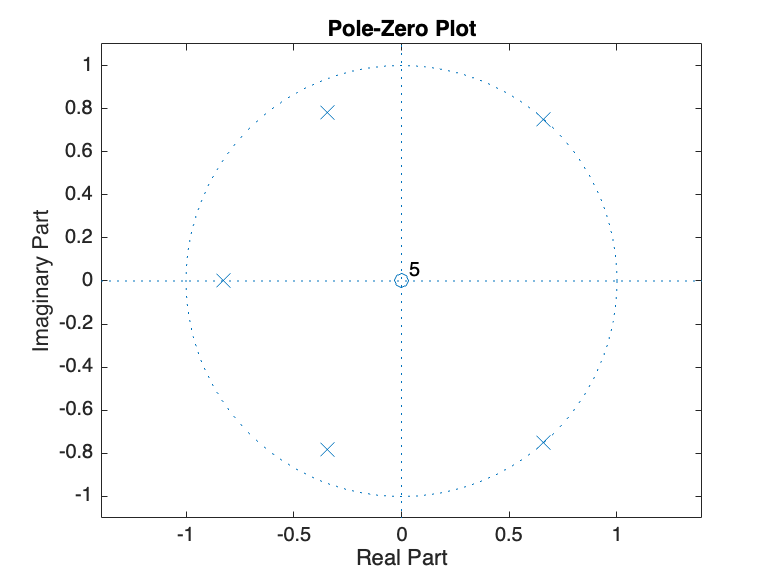

zplane(num,den);


ki = poly2rc(den);
disp('Stability test parameters are');

Stability test parameters are


disp(ki);

   -0.6087
    0.7958
    0.6742
    0.5938
    0.6000

